
                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400           22.47           446.4        0
    2              590           14.98           319.3        0
    3              780          -20.59           193.9        0
    4              970          -31.72           123.9        0
    5             1160          -52.59              70        0
    6             1350          -59.64           19.58        0
    7             1540          -66.11          -14.47        0
    8             1730          -66.11          -33.42        1
    9             1920          -67.71          -46.79        0
   10             2110          -69.71          -55.13        0
   11             2300          -71.31          -59.43        0
   12             2490          -71.31          -61.23        1
   13             2680          -71.31             -64        2
   14             2870          -

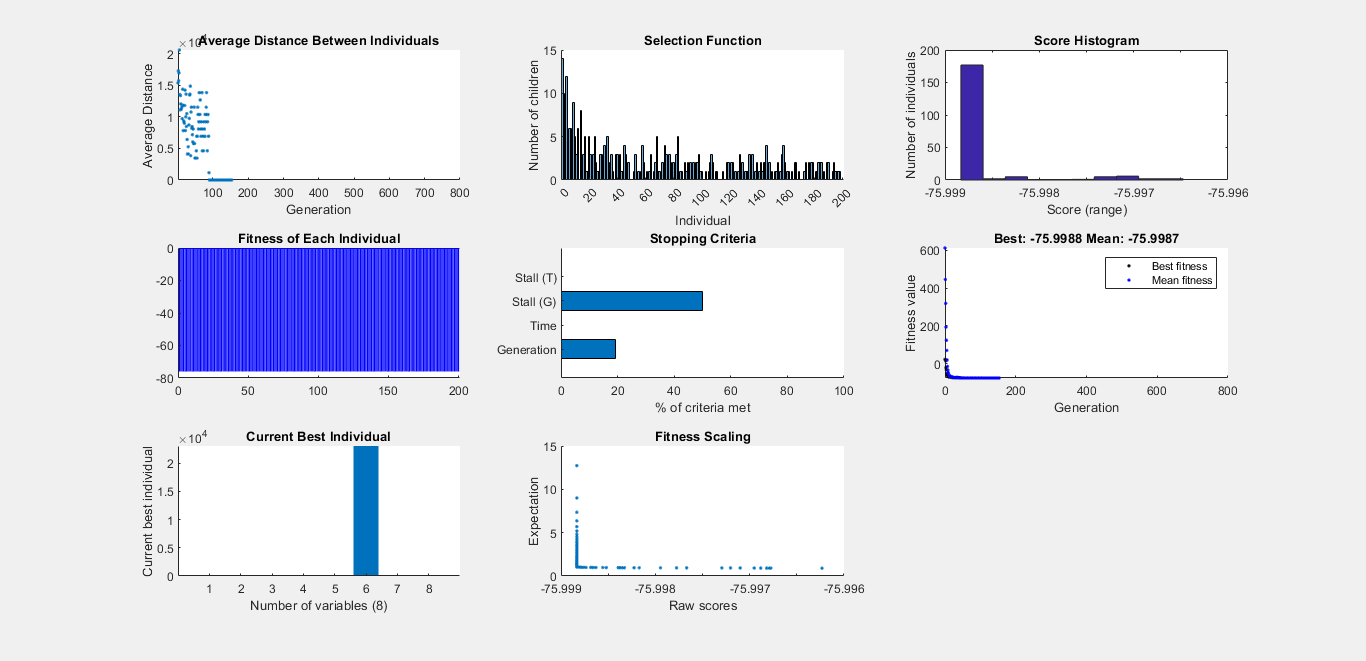

% Set nondefault solver options
options4 = optimoptions('ga','CrossoverFcn','crossoverheuristic',...
    'SelectionFcn','selectionroulette','Display','iter','PlotFcn',...
    {'gaplotdistance','gaplotselection','gaplotscorediversity',...
    'gaplotscores','gaplotstopping','gaplotbestf','gaplotbestindiv',...
    'gaplotexpectation'});

% Solve
[solution,objectiveValue] = ga(fitfun,nVar,[],[],[],[],LB,UB,[],[],options4);

% Clear variables
clearvars options4